## Dynamical analysis

We plan to extend the definition provided for kinematic analysis for data required by dynamical analysis (inertias and forces).

Next we will form equations of motion for the system of unconstrained bodies.

Finally we will solve the general multibody equations of motion.

### Bodies, inertias, and coordinates

Solve the pendulum as multibody system and compare results with differential equation 


$$I_0 \theta^¨ =-\textrm{mg}\frac{l}{2}\sin \theta$$


% Pendulum data
m = 2.0;
l = 5.0;
theta0 = deg2rad(90);
g = 9.81;
Io = m*l^2/12;
tf = 2.0;


Solution using MBD method

mbs = init_mbs();
mbs = add_body(mbs, "ground");
bodies = 5;
indv_l = l/bodies;
indv_m = m/bodies;
indv_Io = indv_m*indv_l^2/12;
mbs = add_body(mbs, "beam1", 0.5*indv_l, 0, 'm', indv_m, 'Ic', indv_Io);
mbs = add_body(mbs, "beam2", 0.5*indv_l, 0, 'm', indv_m, 'Ic', indv_Io);
mbs = add_body(mbs, "beam3", 0.5*indv_l, 0, 'm', indv_m, 'Ic', indv_Io);
mbs = add_body(mbs, "beam4", 0.5*indv_l, 0, 'm', indv_m, 'Ic', indv_Io);
mbs = add_body(mbs, "beam5", 0.5*indv_l, 0, 'm', indv_m, 'Ic', indv_Io);
mbs = add_body(mbs, "mass",  -0.1,0, 'm', 1.0, 'Ic', 0.1);

% Simple joints
mbs = add_simple_joint(mbs, "groundx", "ground", "x", 0);
mbs = add_simple_joint(mbs, "groundy", "ground", "y", 0);
mbs = add_simple_joint(mbs, "groundangle", "ground", "fi", 0);

mbs = add_revolute(mbs, "revO", "ground", [0; 0], "beam1", [-0.5 * indv_l, 0.0]);
mbs = add_revolute(mbs, "rev1", "beam1", [0.5 * indv_l; 0], "beam2", [-0.5 * indv_l, 0.0]);
mbs = add_revolute(mbs, "rev2", "beam2", [0.5 * indv_l; 0], "beam3", [-0.5 * indv_l, 0.0]);
mbs = add_revolute(mbs, "rev3", "beam3", [0.5 * indv_l; 0], "beam4", [-0.5 * indv_l, 0.0]);
mbs = add_revolute(mbs, "rev4", "beam4", [0.5 * indv_l; 0], "beam5", [-0.5 * indv_l, 0.0]);
mbs = add_revolute(mbs, "rev_mass", "beam5", [0.5 * indv_l; 0], "mass", [0.0, 0.0]);


f = -10;
k = 100;
% Add rotational spring
mbs = add_rotational_spring(mbs,"spring1", "ground","beam1",[deg2rad(10),k]);
mbs = add_rotational_spring(mbs,"spring2", "beam1","beam2",[deg2rad(10),k/2]);
mbs = add_rotational_spring(mbs,"spring3", "beam2","beam3",[deg2rad(10),k/3]);
mbs = add_rotational_spring(mbs,"spring4", "beam3","beam4",[deg2rad(10),k/4]);
mbs = add_rotational_spring(mbs,"spring5", "beam4","beam5",[deg2rad(10),k/5]);
mbs = add_scaled_force(mbs,"scaled_force","mass",[0,f]);


q0 = initial_position(mbs);
qd0 = zeros(size(q0));
h = 0.002;
accfun = @(t,q)acceleration(mbs, q, t);
[t2, Q, Qp] = eqn_of_motion(accfun, tf, q0, qd0, h);

84 successful steps
12 failed attempts
577 function evaluations


Compare results with reference

% Calculate refrence
E = 200; % Young's Modulus of Structural ASTM-A36 
x = linspace(0,f, length(t));
d = ((x ) * (l).^3)/ (3*E*Io);


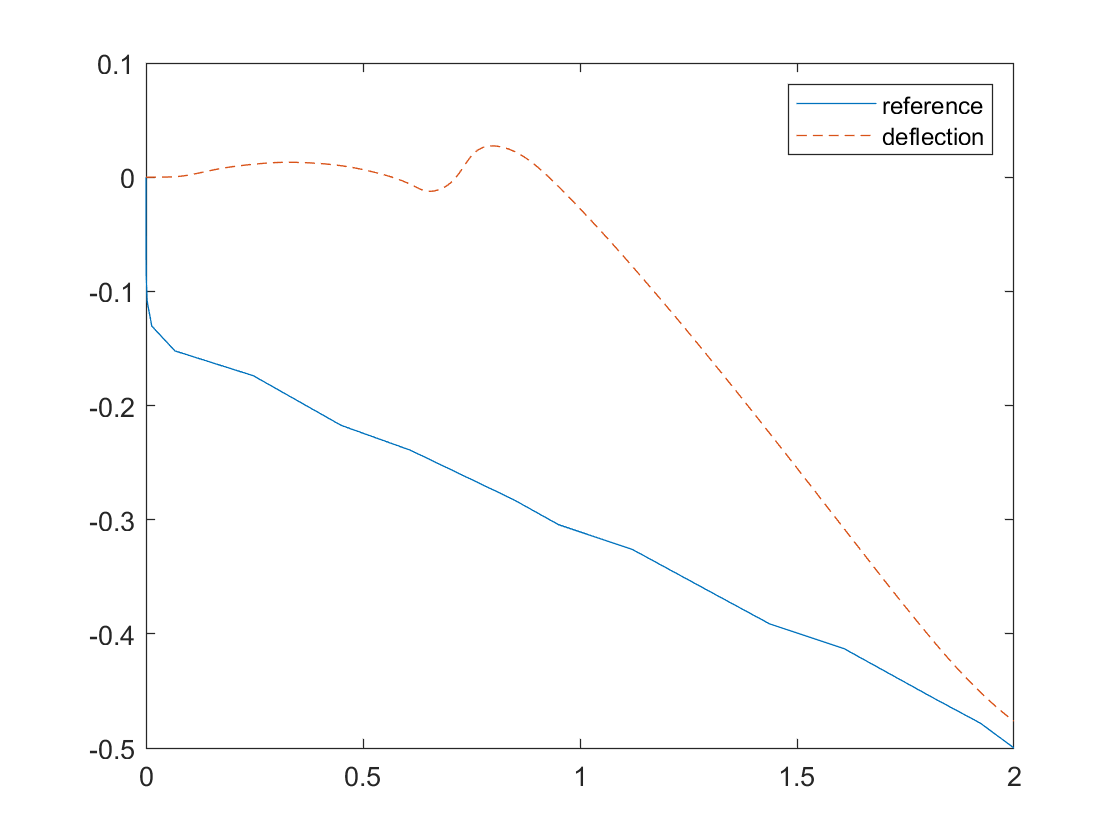

plot(t,d ,t2, Q(:, 20), '--');
legend('reference', 'deflection');
exportgraphics(gcf,'output-cantilever-multi.png','Resolution',300)